# Mechanical Nonlinear Model of a double inverted pendulum on rails

Professor:  Dr. Helon Vicente Hultmann Ayala (helon@puc-rio.br)

## 1. Pre-processing

The following convention is used: 

- 0 refers to the cart;

- 1 refers to the lower pendulum;

- 2 refers to the upper pendulum.

### a. User inputs

The event horizon is composed of N events (+1 for the current initial condition) that span over T seconds

% Clean up
clear
close all
clc

T = 0.01; % Sampling time (s)
N = 19;   % Number of predictions

Next, we define the boundaries for important quantities

% Force applied to the cart (N)
F_min = -1e3; F_max = +1e3;
% Limits of the cart rail (m)
x_min = -1; x_max = +1;
% Limits of the angle of the pendulums (deg->rad)
% theta1_min = -inf; theta1_max = +inf;
% theta2_min = -inf; theta2_max = +inf;

The weights of variable is defined here for convenience. They are needed to define the objective (or cost) function. Variables with higher weights induces the controller to want to minimize the error of that variable more than those with lower weights.

% Weight matrix for the associated with the state vector
Q = eye(6);
% Position and speed of the cart, respectively
Q(1,1) = 0.1; Q(4,4) = 0;
% Angular positions of the lower and upper pendulums, respectively
Q(2,2) = 1; Q(3,3) = 1;
% Angular velocities of the lower and upper pendulums, respectively
Q(5,5) = 1e-5; Q(6,6) = 1e-5;
% Weight associated with the control vector
R = 1e-6; % Only 1 component since the only control variable is the force F
S = 1e-6;

### b. Parameters of the system

The following parameters are defined in the SI.

% Center of mass (m)
l1 = 0.273;
l2 = 0.245;
% Length of each pendulum (m)
L1 = 0.490;
L2 = 0.490;
% Mass (kg
M1 = 0.123;
M2 = 0.092;
M0 = 0.818-M1-M2;
% Mass moment of inertia (kg*m²)
J1 = 0.0362 - M1*l1^2- M2*l2^2;
J2 = 0.00873-M2*l2^2;
% Friction constant
F0 = 2.21;    % (kg/s)
F1 = 0.00164; % (kg/s²)
F2 = 0.00050; % (kg/s²)
% Gravity acelleration (m/s²)
g = 9.8;

Source: K. Furuta, T. Okutani, H. Sone, Computer control of a double inverted pendulum, Computers & Electrical Engineering, Volume 5, Issue 1, 1978, Pages 67-84, ISSN 0045-7906, [https://doi.org/10.1016/0045-7906(78)90018-6.](https://doi.org/10.1016/0045-7906(78)90018-6.)

## 2. Symbolic variables (using CasADi)

First we import the add-on.

% Change this to the CasADi path in your device
addpath('D:\Casadi\casadi-windows-matlabR2016a-v3.5.5')
import casadi.*

### a. State and control variables

The state variables are

- $x$: Position on the cart on the rails;

- $\theta_1$: Angle between the vertical and the lower pendulum;

- $\theta_2$: Angle between the vertical and the upper pendulum.

For the space-state representation, we use the following convention


$$\pmatrix{q_1\cr q_2\cr q_3\cr\dot q_1\cr\dot q_2\cr\dot q_3}=\pmatrix{x\cr\theta_1\cr\theta_2\cr \dot x\cr\dot\theta_1\cr\dot\theta_2}$$


In what follows, we use this naming convention:

- No index: cart;

- Index 1: Lower pendulum;

- Index 2: Upper pendulum.

We define a vector of state variables defined with SX.sym function from CasADi

% Positions
x = SX.sym('x');             % (m)
theta1 = SX.sym('theta1');   % (rad)
theta2 = SX.sym('theta2');   % (rad)
% Velocities
dx = SX.sym('dx');           % (m/s)
dtheta1 = SX.sym('dtheta1'); % (rad/s)
dtheta2 = SX.sym('dtheta2'); % (rad/s)
% State vector
states = [x;theta1;theta2;dx;dtheta1;dtheta2];
n_states = length(states); % Length of the state vector

The only control variable in our system is the force $F$ on the cart.

% Force on the cart (N)
F = SX.sym('F');
% Control vector
controls = F;
n_controls = length(controls); % Length of the control vector

### b. Derivative of the state vector $dx/dt$

This has been derivative of the state vector is defined as:


$$\frac{d\mathbf x}{dt}=\pmatrix{\dot x\cr\dot\theta_1\cr\dot\theta_2\cr \ddot x\cr\ddot\theta_1\cr\ddot\theta_2}$$


Notice that the first 3 rows of $d\mathbf{x}/dt$ are the last 3 of $\mathbf x$. The remaining rows were derived in the *livescript* Model.mlx (the symbolic variables were renamed to follow the convention of this text).

% Right-hand side of the ODE f(x,t) = dx/dt
rhs = [
  dx;
  dtheta1;
  dtheta2;
  (2*F*J1*J2 + 2*F*J2*M1*l1^2 + 2*F*J1*M2*l2^2 - 2*F0*J1*J2*dx + F*L1^2*M2^2*l2^2 + 2*F*J2*L1^2*M2 - F*L1^2*M2^2*l2^2*cos(2*theta1 - 2*theta2) - F0*L1^2*M2^2*l2^2*dx - 2*F0*J2*L1^2*M2*dx - 2*F0*J2*M1*l1^2*dx - 2*F0*J1*M2*l2^2*dx - J2*L1^2*M2^2*g*sin(2*theta1) + 2*J2*L1^3*M2^2*dtheta1^2*sin(theta1) - J2*M1^2*g*l1^2*sin(2*theta1) - J1*M2^2*g*l2^2*sin(2*theta2) + 2*F*M1*M2*l1^2*l2^2 + 2*J2*M1^2*l1^3*dtheta1^2*sin(theta1) + 2*J1*M2^2*l2^3*dtheta2^2*sin(theta2) + J1*L1*M2^2*l2^2*dtheta1^2*sin(theta1) + J2*L1^2*M2^2*l2*dtheta2^2*sin(theta2) - 2*F0*M1*M2*l1^2*l2^2*dx + 2*J1*J2*L1*M2*dtheta1^2*sin(theta1) - F2*L1^2*M2^2*l2*cos(2*theta1 - theta2)*dtheta2 - J1*L1*M2^2*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + 2*J1*J2*M1*l1*dtheta1^2*sin(theta1) + 2*J1*J2*M2*l2*dtheta2^2*sin(theta2) - M1^2*M2*g*l1^2*l2^2*sin(2*theta1) - M1*M2^2*g*l1^2*l2^2*sin(2*theta2) + F0*L1^2*M2^2*l2^2*cos(2*theta1 - 2*theta2)*dx + 2*M1^2*M2*l1^3*l2^2*dtheta1^2*sin(theta1) + 2*M1*M2^2*l1^2*l2^3*dtheta2^2*sin(theta2) + F1*L1*M2^2*l2^2*dtheta1*cos(theta1) + F2*L1^2*M2^2*l2*dtheta2*cos(theta2) + J2*L1^2*M2^2*l2*dtheta2^2*sin(2*theta1 - theta2) + 2*F1*J2*L1*M2*dtheta1*cos(theta1) - F1*L1*M2^2*l2^2*cos(theta1 - 2*theta2)*dtheta1 + 2*F1*J2*M1*l1*dtheta1*cos(theta1) + 2*F2*J1*M2*l2*dtheta2*cos(theta2) + 2*J2*L1*M1*M2*l1^2*dtheta1^2*sin(theta1) + 2*J2*L1^2*M1*M2*l1*dtheta1^2*sin(theta1) + L1*M1*M2^2*l1*l2^3*dtheta2^2*sin(2*theta1 - theta2) - L1*M1*M2^2*l1^2*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + L1^2*M1*M2^2*l1*l2^2*sin(theta1 - 2*theta2)*dtheta1^2 + 2*J1*M1*M2*l1*l2^2*dtheta1^2*sin(theta1) + 2*J2*M1*M2*l1^2*l2*dtheta2^2*sin(theta2) - L1*M1*M2^2*g*l1*l2^2*sin(2*theta1) + L1*M1*M2^2*g*l1*l2^2*sin(2*theta2) - L1*M1*M2^2*l1*l2^3*dtheta2^2*sin(theta2) - 2*J2*L1*M1*M2*g*l1*sin(2*theta1) + 2*F1*M1*M2*l1*l2^2*dtheta1*cos(theta1) + 2*F2*M1*M2*l1^2*l2*dtheta2*cos(theta2) + L1*M1*M2^2*l1^2*l2^2*dtheta1^2*sin(theta1) + L1^2*M1*M2^2*l1*l2^2*dtheta1^2*sin(theta1) - J2*L1*M1*M2*l1*l2*dtheta2^2*sin(theta2) - F2*L1*M1*M2*l1*l2*cos(2*theta1 - theta2)*dtheta2 - F2*L1*M1*M2*l1*l2*dtheta2*cos(theta2) + J2*L1*M1*M2*l1*l2*dtheta2^2*sin(2*theta1 - theta2))/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2));
  -(F1*M2^2*l2^2*dtheta1 + 2*F1*J2*M0*dtheta1 + 2*F1*J2*M1*dtheta1 + 2*F1*J2*M2*dtheta1 - 2*J2*M1^2*g*l1*sin(theta1) + J2*L1^2*M2^2*sin(2*theta1)*dtheta1^2 + J2*M1^2*l1^2*sin(2*theta1)*dtheta1^2 + F*L1*M2^2*l2^2*cos(theta1) + 2*F*J2*L1*M2*cos(theta1) - F*L1*M2^2*l2^2*cos(theta1 - 2*theta2) + 2*F1*M0*M2*l2^2*dtheta1 + 2*F1*M1*M2*l2^2*dtheta1 + 2*F*J2*M1*l1*cos(theta1) - F1*M2^2*l2^2*cos(2*theta2)*dtheta1 - 2*J2*L1*M2^2*g*sin(theta1) - 2*J2*M0*M1*g*l1*sin(theta1) - 2*J2*M1*M2*g*l1*sin(theta1) + J2*L1*M2^2*l2*sin(theta1 - theta2)*dtheta2^2 + M1^2*M2*l1^2*l2^2*sin(2*theta1)*dtheta1^2 + M1*M2^2*g*l1*l2^2*sin(theta1 - 2*theta2) + L1^2*M0*M2^2*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + L1^2*M1*M2^2*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + M1*M2^2*l1*l2^3*dtheta2^2*sin(theta1 + theta2) + F2*L1*M2^2*l2*dtheta2*cos(theta1 + theta2) + 2*F*M1*M2*l1*l2^2*cos(theta1) + 2*L1*M0*M2^2*l2^3*sin(theta1 - theta2)*dtheta2^2 + 2*L1*M1*M2^2*l2^3*sin(theta1 - theta2)*dtheta2^2 - M1*M2^2*l1*l2^3*sin(theta1 - theta2)*dtheta2^2 - F2*L1*M2^2*l2*cos(theta1 - theta2)*dtheta2 + J2*L1*M2^2*l2*dtheta2^2*sin(theta1 + theta2) - F0*L1*M2^2*l2^2*dx*cos(theta1) - L1*M0*M2^2*g*l2^2*sin(theta1) - L1*M1*M2^2*g*l2^2*sin(theta1) - 2*F0*J2*L1*M2*dx*cos(theta1) - 2*J2*L1*M0*M2*g*sin(theta1) - 2*J2*L1*M1*M2*g*sin(theta1) - M1*M2^2*g*l1*l2^2*sin(theta1) - 2*M1^2*M2*g*l1*l2^2*sin(theta1) + F0*L1*M2^2*l2^2*cos(theta1 - 2*theta2)*dx - L1*M0*M2^2*g*l2^2*sin(theta1 - 2*theta2) - L1*M1*M2^2*g*l2^2*sin(theta1 - 2*theta2) - 2*F0*J2*M1*l1*dx*cos(theta1) - J2*M1*M2*l1*l2*sin(theta1 - theta2)*dtheta2^2 + 2*J2*L1*M1*M2*l1*sin(2*theta1)*dtheta1^2 - L1*M1*M2^2*l1*l2^2*dtheta1^2*sin(2*theta1 - 2*theta2) + F2*M1*M2*l1*l2*dtheta2*cos(theta1 + theta2) - 2*F2*L1*M0*M2*l2*cos(theta1 - theta2)*dtheta2 - 2*F2*L1*M1*M2*l2*cos(theta1 - theta2)*dtheta2 + F2*M1*M2*l1*l2*cos(theta1 - theta2)*dtheta2 + J2*M1*M2*l1*l2*dtheta2^2*sin(theta1 + theta2) - 2*F0*M1*M2*l1*l2^2*dx*cos(theta1) - 2*M0*M1*M2*g*l1*l2^2*sin(theta1) + 2*J2*L1*M0*M2*l2*sin(theta1 - theta2)*dtheta2^2 + 2*J2*L1*M1*M2*l2*sin(theta1 - theta2)*dtheta2^2 + L1*M1*M2^2*l1*l2^2*sin(2*theta1)*dtheta1^2)/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2));
  (2*J1*M2^2*g*l2*sin(theta2) - F2*M1^2*l1^2*dtheta2 - 2*F2*J1*M0*dtheta2 - 2*F2*J1*M1*dtheta2 - 2*F2*J1*M2*dtheta2 - F2*L1^2*M2^2*dtheta2 - J1*M2^2*l2^2*sin(2*theta2)*dtheta2^2 - F*L1^2*M2^2*l2*cos(theta2) - 2*F2*L1^2*M0*M2*dtheta2 - 2*F2*L1^2*M1*M2*dtheta2 - 2*F2*M0*M1*l1^2*dtheta2 - 2*F2*M1*M2*l1^2*dtheta2 - 2*F*J1*M2*l2*cos(theta2) + F2*L1^2*M2^2*cos(2*theta1)*dtheta2 + F2*M1^2*l1^2*cos(2*theta1)*dtheta2 + F*L1^2*M2^2*l2*cos(2*theta1 - theta2) + 2*J1*M0*M2*g*l2*sin(theta2) + 2*J1*M1*M2*g*l2*sin(theta2) + J1*L1*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 - M1*M2^2*l1^2*l2^2*sin(2*theta2)*dtheta2^2 + L1^2*M0*M2^2*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) + L1^2*M1*M2^2*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) - M1^2*M2*l1^3*l2*dtheta1^2*sin(theta1 + theta2) - F1*L1*M2^2*l2*dtheta1*cos(theta1 + theta2) - 2*F*M1*M2*l1^2*l2*cos(theta2) - F0*L1^2*M2^2*l2*cos(2*theta1 - theta2)*dx - L1^2*M0*M2^2*g*l2*sin(2*theta1 - theta2) - L1^2*M1*M2^2*g*l2*sin(2*theta1 - theta2) + 2*L1^3*M0*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*L1^3*M1*M2^2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*F2*L1*M1*M2*l1*dtheta2 + M1^2*M2*g*l1^2*l2*sin(2*theta1 - theta2) - M1^2*M2*l1^3*l2*sin(theta1 - theta2)*dtheta1^2 + F1*L1*M2^2*l2*cos(theta1 - theta2)*dtheta1 - J1*L1*M2^2*l2*dtheta1^2*sin(theta1 + theta2) + F0*L1^2*M2^2*l2*dx*cos(theta2) + L1^2*M0*M2^2*g*l2*sin(theta2) + L1^2*M1*M2^2*g*l2*sin(theta2) + 2*M1*M2^2*g*l1^2*l2*sin(theta2) + M1^2*M2*g*l1^2*l2*sin(theta2) + 2*F0*J1*M2*l2*dx*cos(theta2) - J1*M1*M2*l1*l2*sin(theta1 - theta2)*dtheta1^2 - L1*M1*M2^2*l1*l2^2*dtheta2^2*sin(2*theta1 - 2*theta2) + F*L1*M1*M2*l1*l2*cos(theta2) - F1*M1*M2*l1*l2*dtheta1*cos(theta1 + theta2) + L1*M1*M2^2*g*l1*l2*sin(2*theta1 - theta2) - L1*M1^2*M2*g*l1*l2*sin(2*theta1 - theta2) - L1*M1*M2^2*l1^2*l2*dtheta1^2*sin(theta1 + theta2) + L1*M1^2*M2*l1^2*l2*dtheta1^2*sin(theta1 + theta2) + L1^2*M1*M2^2*l1*l2*dtheta1^2*sin(theta1 + theta2) + 2*F1*L1*M0*M2*l2*cos(theta1 - theta2)*dtheta1 + 2*F1*L1*M1*M2*l2*cos(theta1 - theta2)*dtheta1 - F1*M1*M2*l1*l2*cos(theta1 - theta2)*dtheta1 + 2*F2*L1*M1*M2*l1*cos(2*theta1)*dtheta2 - J1*M1*M2*l1*l2*dtheta1^2*sin(theta1 + theta2) + 2*F0*M1*M2*l1^2*l2*dx*cos(theta2) - 3*L1*M1*M2^2*g*l1*l2*sin(theta2) - L1*M1^2*M2*g*l1*l2*sin(theta2) + 2*M0*M1*M2*g*l1^2*l2*sin(theta2) + F*L1*M1*M2*l1*l2*cos(2*theta1 - theta2) + L1*M1*M2^2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2 + L1*M1^2*M2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2 - 3*L1^2*M1*M2^2*l1*l2*sin(theta1 - theta2)*dtheta1^2 + 2*J1*L1*M0*M2*l2*sin(theta1 - theta2)*dtheta1^2 + 2*J1*L1*M1*M2*l2*sin(theta1 - theta2)*dtheta1^2 + L1*M1*M2^2*l1*l2^2*sin(2*theta2)*dtheta2^2 - F0*L1*M1*M2*l1*l2*cos(2*theta1 - theta2)*dx - L1*M0*M1*M2*g*l1*l2*sin(2*theta1 - theta2) - F0*L1*M1*M2*l1*l2*dx*cos(theta2) - L1*M0*M1*M2*g*l1*l2*sin(theta2) + 2*L1*M0*M1*M2*l1^2*l2*sin(theta1 - theta2)*dtheta1^2)/(J2*L1^2*M2^2 + J2*M1^2*l1^2 + J1*M2^2*l2^2 + 2*J1*J2*M0 + 2*J1*J2*M1 + 2*J1*J2*M2 + 2*J2*M0*M1*l1^2 + 2*J1*M0*M2*l2^2 + 2*J1*M1*M2*l2^2 + 2*J2*M1*M2*l1^2 - J2*L1^2*M2^2*cos(2*theta1) - J2*M1^2*l1^2*cos(2*theta1) - J1*M2^2*l2^2*cos(2*theta2) + L1^2*M0*M2^2*l2^2 + L1^2*M1*M2^2*l2^2 + 2*J2*L1^2*M0*M2 + 2*J2*L1^2*M1*M2 + M1*M2^2*l1^2*l2^2 + M1^2*M2*l1^2*l2^2 - M1^2*M2*l1^2*l2^2*cos(2*theta1) - M1*M2^2*l1^2*l2^2*cos(2*theta2) - L1^2*M0*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1^2*M1*M2^2*l2^2*cos(2*theta1 - 2*theta2) - L1*M1*M2^2*l1*l2^2 + 2*M0*M1*M2*l1^2*l2^2 - 2*J2*L1*M1*M2*l1 - L1*M1*M2^2*l1*l2^2*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta2) - 2*J2*L1*M1*M2*l1*cos(2*theta1) + L1*M1*M2^2*l1*l2^2*cos(2*theta1 - 2*theta2))];

### c. Symbolic variables and functions used in the prediction

We create a Function object $f=d\mathbf x/dt$ that receives the symbolic state and control vectors and outputs the derivative $d\mathbf x/dt$

f = Function('f',{states,controls},{rhs});

The symbolic U contains the decision (control) variables, which are the outputs of the controler. Once again, this system only has 1 control: the force on the cart

U = SX.sym('U',n_controls,N);

The symbolic P contains any parameters needed during the optimization (12 in this case) that may change or not at the start of each MPC iteration.

- The first 6 rows contain the current initial state of the system (updated after each MPC iteration);

- The last 6 rows contain the desired end-state of the system at the current instant. This is constant if the desired set-point is constant,  but otherwise variable.

P = SX.sym('P',n_states + n_states);

The symbolic matrix X contains the state at each instant predicted for a given set of initial conditions P(1:6) and controls.

- X: rows represent each of the 6 state variables, and columns represent each instant in the event horizon (1 initial condition + N predictions);

- U: rows represent the control variables (we have only one, $F$ on the cart), and columns represent each instant in the event horizon (1 initial condition + N predictions);

This is the prediction part of the MPC, where X is predicted symbolically using  a "numerical method". We chose explicit Euler for its simplicity and fine accuracy given a small enough time step T.

% Create symbolic vector X(state,event)
X = SX.sym('X',n_states,(N+1));

% Compute solution symbolically
X(:,1) = P(1:6); % Insert initial state in the first column
for k = 1:N
  % Define current state and control action
  st = X(:,k);  con = U(:,k);
  % Compute derivative of the state vector at current state
  f_value  = f(st,con);
  % Compute next state using desired ODE solution method
  st_next  = st+ (T*f_value);
  % Store the result at the next column of X
  X(:,k+1) = st_next;
end

Function ff computes the prediction X numerically once for a given P and U (this one will be obtained as the solution of the optimization process at each MPC iteration).

getX=Function('ff',{U,P},{X});

### c. Symbolic variables and functions used in the optimization

First, we compute the objective function symbolically for a given set of states and control actions.

obj=0;
for k=1:N
  % Get the state X and control actions U for the each event in the horizon
  st = X(:,k);  con = U(:,k);
  % Compute the objective function using the weigth matrices defined before
  obj = obj+(st-P(7:12))'*Q*(st-P(7:12)) + con'*R*con; % calculate obj
end
% Penalize change of control variables
for k=2:N
  % Get the state X and control actions U for the each event in the horizon
  con0 = U(:,k-1); con = U(:,k);
  % Compute the objective function using the weigth matrices defined before
  obj = obj+ (con-con0)'*S*(con-con0); % calculate obj
end

Next, we compute the contraints, but notice we will not assign the numerical values yet. Now, we just determine that each desired state at each event in the horizon must be within the numerical boundaries defined in the Pre-Processing section (numerical values are added later)

% Initialize contraint vector
g = [];
for k = 1:N+1
  % Get position of the cart at even k
  g = [g ; X(1,k)];
  % Get angle of the lower pendulum at even k
%   g = [g ; X(2,k)];
%   % Get angle of the lower pendulum at even k
%   g = [g ; X(3,k)];
end
% g = [];

The column vector g contains the positions (initial + N predicted) at each row following the sequence: postion of the cart; angle of the lower pendulum; angle of the upper pendulum. This repeats N+1 times thus, the size of the vector is 3*(N+1).

### d. Make optimization object

We need to define two optimization structs before creating the optimization variables.

%% Montar objeto de otimização
OPT_variables = reshape(U,1*N,1);
nlp_prob = struct('f', obj, 'x', OPT_variables, 'g', g, 'p', P);

opts = struct;
opts.ipopt.max_iter = 100;
opts.ipopt.print_level =0;%0,3
opts.print_time = 0;
opts.ipopt.acceptable_tol =1e-8;
opts.ipopt.acceptable_obj_change_tol = 1e-6;

solver = nlpsol('solver', 'ipopt', nlp_prob,opts);

opts = struct;
opts.ipopt.max_iter = 100;
opts.ipopt.print_level =0;%0,3
opts.print_time = 0;
opts.ipopt.acceptable_tol =1e-8;
opts.ipopt.acceptable_obj_change_tol = 1e-6;

solver = nlpsol('solver', 'ipopt', nlp_prob,opts);

%% struct de restrições
args = struct;

% Restrições dos estados
args.lbg = x_min;  % Valor mínimo de theta1 e theta2
args.ubg = x_max;   % Valor mínimo de theta1 e theta2
% args.lbg = -2*pi;  % Valor mínimo de theta1 e theta2
% args.ubg = +2*pi;   % Valor mínimo de theta1 e theta2
% args.lbg = deg2rad(-1);  % Valor mínimo de theta1 e theta2
% args.ubg = deg2rad(+1);   % Valor mínimo de theta1 e theta2

% inequality constraints (state constraints)
% args.lbg = -2;  % lower bound of the states x and y
% args.ubg = 2;   % upper bound of the states x and y

% Restrições da ação de controle (F: força no carrinho)
args.lbx(1:N,1) = F_min;
args.ubx(1:N,1) = F_max;

%% Condições iniciais
t0 = 0;
x0 = [0 ; deg2rad(0) ; deg2rad(45); 0; 0; 0];    % initial condition.
xs = [0 ; 0 ; 0; 0 ; 0 ; 0]; % Valor desejado.

% t0 = 0;
% x0 = [0 ; 0 ; 0];    % initial condition.
% xs = [1.5 ; 1.5 ; 0]; % Reference posture.

%% Histórico de eventos
xx(:,1) = x0; % xx contains the history of states
t(1) = t0;

% Previsão de controle em cada iteração de MPC
u0 = zeros(N,1);

% u0 = zeros(N,2);  % two control inputs

% Tempo de simulação
sim_tim = 1 ; % Maximum simulation time

% Start MPC
mpciter = 0;
xx1 = [];
u_cl=[];

%% Simulação
% the main simulaton loop... it works as long as the error is greater
% than 10^-2 and the number of mpc steps is less than its maximum
% value.
main_loop = tic;
while(norm((x0-xs),2) > 1e-2 && mpciter < sim_tim / T)
  % args.p: [estado atual, estado desejado no final]
  args.p   = [x0;xs]; % set the values of the parameters vector
  % ars.x0: AÇÃO DE CONTROLE atual (zero no começo, mas nas iterações
  % seguintes usa-se a solução anterior como chute inicial!)
  args.x0 = reshape(u0',1*N,1); % initial value of the optimization variables
  %tic
  sol = solver('x0', args.x0, 'lbx', args.lbx, 'ubx', args.ubx,...
    'lbg', args.lbg, 'ubg', args.ubg,'p',args.p);
  %toc

  % A ação de controle nos N eventos é guardada em u
  u = reshape(full(sol.x)',1,N)'; % 1 ação de controle só
  %     u = reshape(full(sol.x)',2,N)';

  % A estimativa dos estados a partir de u e args.p é computada:
  ff_value = getX(u',args.p); % compute OPTIMAL solution TRAJECTORY
  % Mas apenas o próximo evento (de N) é adotado para simulação
  xx1(:,1:6,mpciter+1)= full(ff_value)';

  %     xx1(:,1:3,mpciter+1)= full(ff_value)';

  % Guardar apenas a primeira ação de controle no histórico, pois as
  % próximas "são jogadas fora" (na vdd são usadas como chute inicial da
  % próxima iteração do MPC)
  u_cl= [u_cl ; u(1,:)];

  % Guardar valor do instante de tempo
  t(mpciter+1) = t0;

  % Dar 1 passo pra frente T segundo no tempo, estado e controle!
  [t0, x0, u0] = shift(T, t0, x0, u,f); % get the initialization of the next optimization step

  xx(:,mpciter+2) = x0;
%   mpciter
  mpciter = mpciter + 1;
end
main_loop_time = toc(main_loop)

main_loop_time = 7.6184


ss_error = norm((x0-xs),2)

ss_error = 2.7556

## Animation

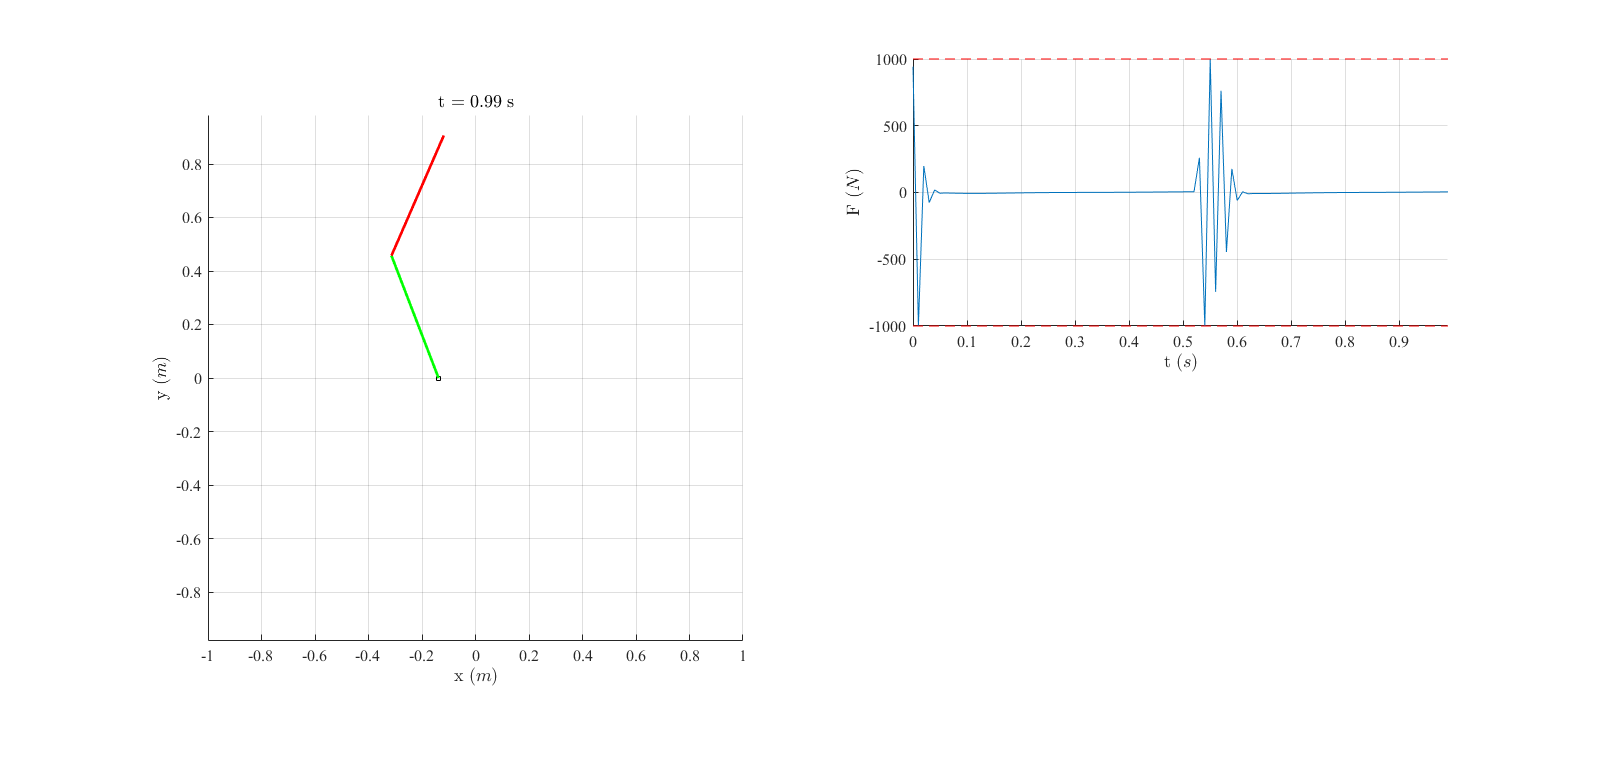

set(0,'DefaultFigureWindowStyle','normal')

% L1 = 0.490;
% L2 = 0.490;
% Plor cart

for i = 1:length(t)
  set(gcf,'Visible','on')
  set(gcf,'color','white')
  % Update states
  x_cart = xx(1,i);
  t1 = xx(2,i); % theta1
  t2 = xx(3,i); % theta2
  x1 = x_cart + L1*sin(t1);
  x2 = x1 + L2*sin(t2);
  y_cart = 0;
  y1 = y_cart + L1*cos(t1);
  y2 = y1 + L2*cos(t2);
  clf
  subplot(2,2,[1 3])
  hold on
  grid on
  %   axis((L1+L2)*[-1 +1 -1 +1])
  ylim((L1+L2)*[-1 +1])
  axis equal
  % Plot the cart
  plot(x_cart,y_cart,'ks','markersize',5)
  % Plot the lower pendulum
  plot([x_cart x1],[y_cart y1],'-g','linewidth',2)
  % Plot the upper pendulum
  plot([x1 x2],[y1 y2],'-r','linewidth',2)
  hold off
  %   legend({'Cart';'Lower pendulum';'Upper pendulum'},...
  %     'interpreter','latex','location','nw')
  grid on
  titulo = sprintf('t = %g s',t(i));
  title(titulo,'interpreter','latex')
  xlabel('x $(m)$','Interpreter',"latex")
  ylabel('y $(m)$','Interpreter',"latex")
  xlim([x_min,x_max])


  % Plot control action
  subplot(2,2,2)
  hold on
  plot(t(1:i),u_cl(1:i))
  plot([0 t(end)],[F_min F_min],'--r')
  plot([0 t(end)],[F_max F_max],'--r')
  hold off
  %   ylim(1e3*[-6 4])
  axis tight
  xlim([0 t(end)])
  grid on
  xlabel('t $(s)$','Interpreter',"latex")
  ylabel('F $(N)$','Interpreter',"latex")

  pause(.001)
end